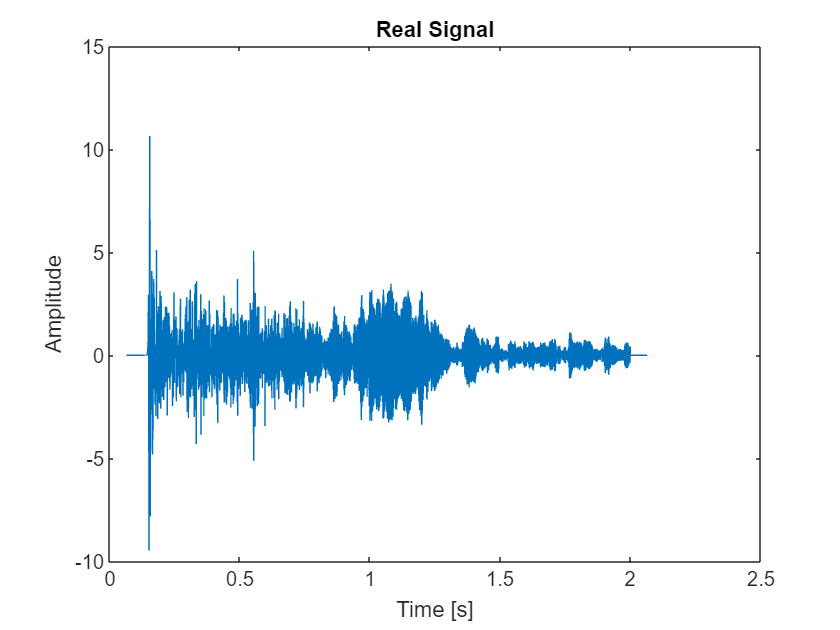

% read the real signal first as a reference
fs = 2^14; % sampling frequency

root_dir = "C:\Users\gfd9111\OneDrive - AUT University\PUCV Supernova Project\PUCV-AUT-main\PUCV-AUT-main\Data\Simulate_GWs\pure signal";
sig_real = importdata(fullfile(root_dir, "gw_s11.2--LS220--GravA.dat"));
sig_real_t = sig_real(:,1); % time vector
sig_real_sig = normalize(sig_real(:,2)); % signal vector, normalized
% inspect time domain signal
figure, plot(sig_real_t, sig_real_sig), xlabel("Time [s]"), ylabel("Amplitude"), title("Real Signal")

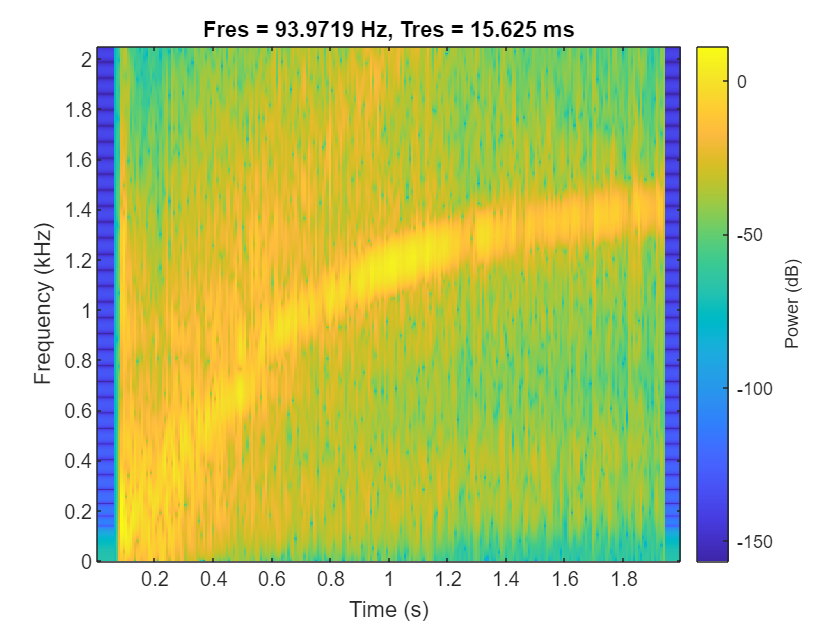

% inspect the spectrogram
[p ,f, t] = pspectrum(sig_real_sig,fs,'spectrogram','OverlapPercent',50, 'FrequencyLimit', [0 2048],...
    'Leakage',0.85, 'TwoSided', false);
pspectrum(sig_real_sig,fs,'spectrogram','OverlapPercent',50, 'FrequencyLimit', [0 2048],...
    'Leakage',0.85, 'TwoSided', false)

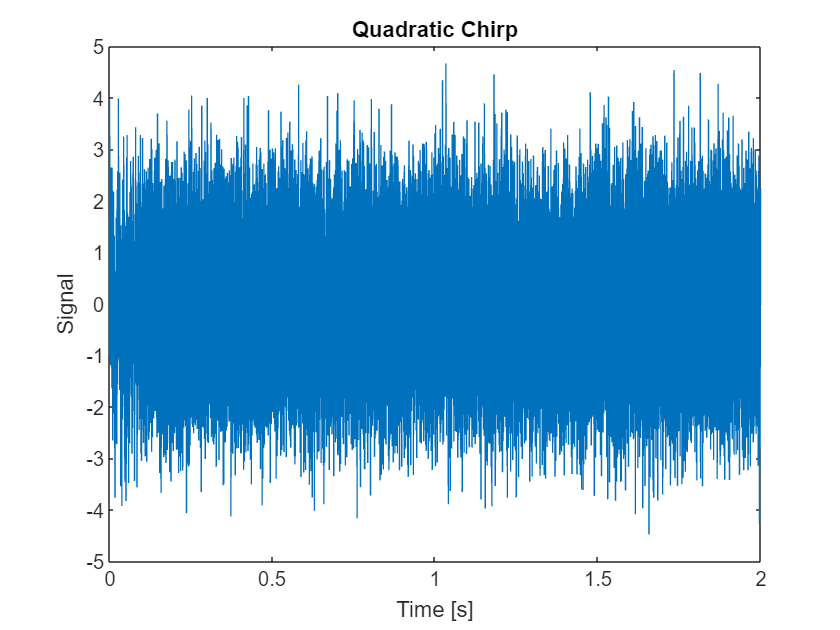

% quadratic chirp
duration = 2; % signal duration
time = 0:1/fs:duration; % time vector
y = chirp(time, 15, duration, 1500, 'quadratic', 0, 'convex'); % generate the signal
y = y + randn(1,length(y)); % adding some perturbation
% inspect the signal
figure, plot(time, y), xlabel("Time [s]"), ylabel("Signal"), title("Quadratic Chirp")

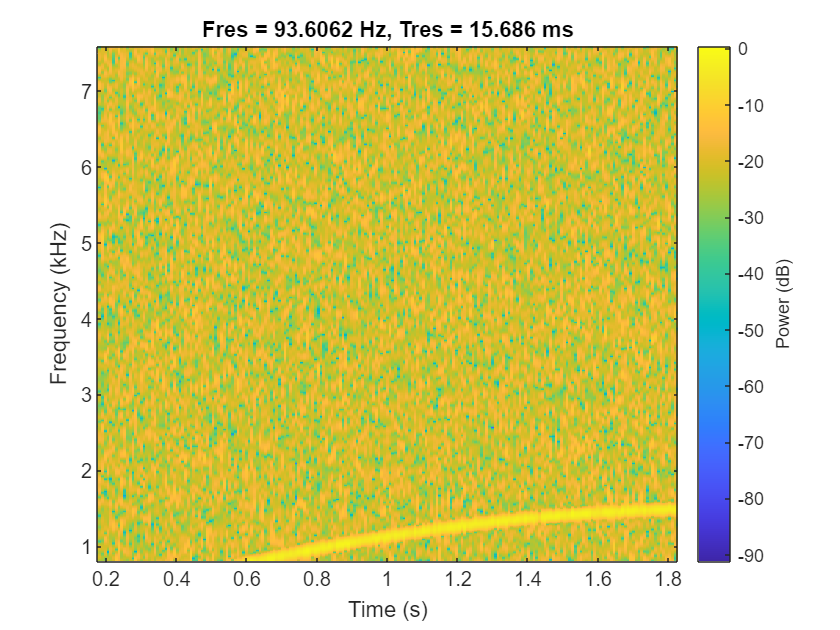

% inspect the spectrogram
[p,f,t] = pspectrum(y,fs,'spectrogram','OverlapPercent',50,'Leakage',0.85, 'TwoSided', false);
pspectrum(y,fs,'spectrogram','OverlapPercent',50,'Leakage',0.85, 'TwoSided', false)

% save the signal
fileID = fopen('quadratic_chirp.txt', 'w');
for i = 1:length(y)-1
    fprintf(fileID, '%d %d\n', time(i), y(i));
end
fclose(fileID);

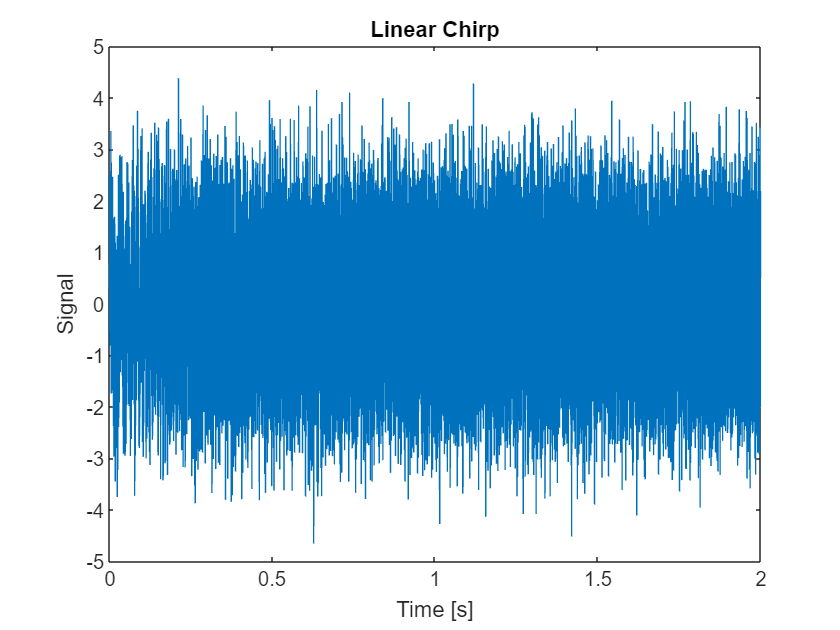

% linear chirp
duration = 2; % signal duration
time = 0:1/fs:duration; % time vector
y = chirp(time, 15, duration, 1500, 'linear'); % generate the signal
y = y + randn(1,length(y)); % adding some perturbation
% inspect the signal
figure, plot(time, y), xlabel("Time [s]"), ylabel("Signal"), title("Linear Chirp")

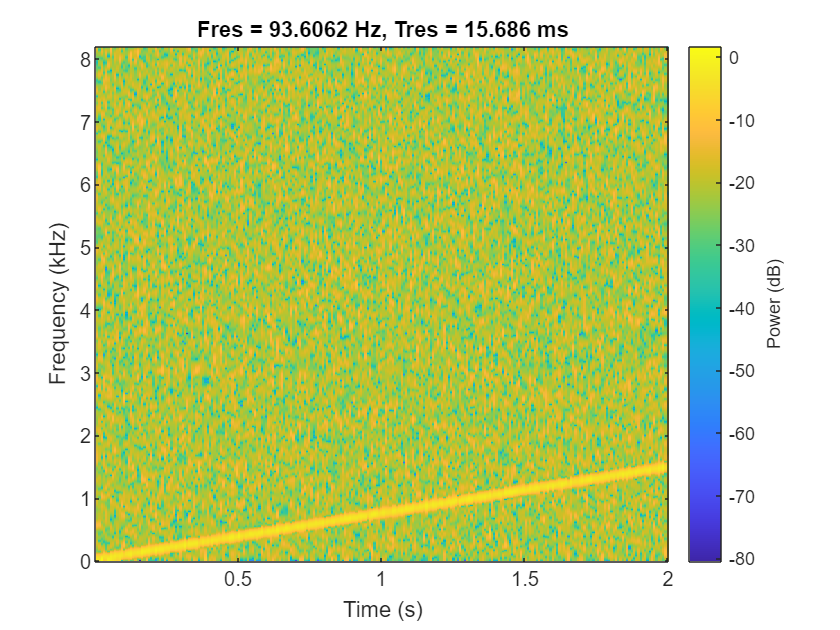

% inspect the spectrogram
[p,f,t] = pspectrum(y,fs,'spectrogram','OverlapPercent',50,'Leakage',0.85, 'TwoSided', false);
pspectrum(y,fs,'spectrogram','OverlapPercent',50,'Leakage',0.85, 'TwoSided', false)

% save the signal
fileID = fopen('linear_chirp.txt', 'w');
for i = 1:length(y)-1
    fprintf(fileID, '%d %d\n', time(i), y(i));
end
fclose(fileID);